DH parameters were given in the assignment, the robot can be created using the RigidBodyTree object as shown below.

dhparams = [.205, 0 .220 0;
    .275, 0 0 0;
    0, 0, 0, 0;
    0, 0, 0, 0];

robot = robotics.RigidBodyTree;

body1 = robotics.RigidBody('body1');
jnt1 = robotics.Joint('jnt1','revolute');
body2 = robotics.RigidBody('body2');
jnt2 = robotics.Joint('jnt2','revolute');
body3 = robotics.RigidBody('body3');
jnt3 = robotics.Joint('jnt3','prismatic');
body4 = robotics.RigidBody('body4');
jnt4 = robotics.Joint('jnt4','revolute');


setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');
addBody(robot,body4,'body3');

showdetails(robot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


fig = show(robot)

fig =   Axes (Primary) with properties:

             XLim: [-528 528]
             YLim: [-528 528]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


Next, to show the motion of the robot end effector we can find the homogenous transformation matrix with each different joint configuration. The trajectories are generated over 2 seconds, as that is the period of the theta2 motion. This should give a full cycle of movement. Then for each point in the generated joint trajectories, the correspond TF matrix is found using the getTransform command. From this matrix the x y and z components are extracted and plotted on the same graph as the Robot model in its base configuration.


%create struct for joints
joints = homeConfiguration(robot)

joints = 1×4 struct array with fields:
    JointName
    JointPosition



%create joint position trajectory
t = 0:0.01:2

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


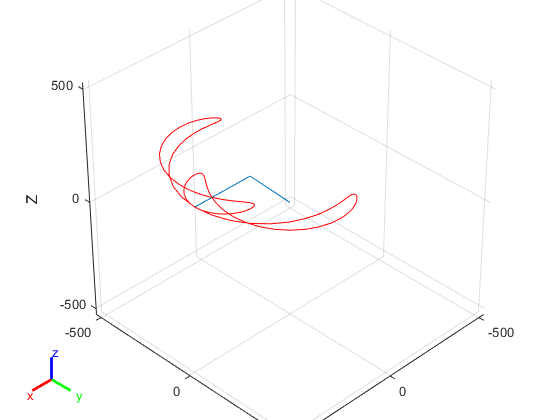

theta1 = (-pi/4)*sin(2*pi.*t);
theta2 = (pi/2)*sin(4*pi.*t);
x_ps = zeros(length(t));
y_ps = zeros(length(t));
z_ps = zeros(length(t));

%iterate through joint trajectory to make tfs
for i = 1:length(theta2)
    joints(1).JointPosition = theta1(i);
    joints(2).JointPosition = theta2(i);
    transform = getTransform(robot,joints,'body3');
    %add x y and z to array 
    % plot x y and z
    x_ps(i) = transform(1,4);
    y_ps(i) = transform(2,4);
    z_ps(i) = transform(3,4);
end

hold on
plot3(fig,x_ps,y_ps,z_ps,'color','red');
view([45,45,45])